# Demo for managing bad trials..

## Load path


loadpath; %path for eeglab
S.eeg_filepath = '/work/imagingP/SpatialAttention_Drowsiness/Scripts/manage_badTrials/';
S.eeg_filename = 'demo'

S =     eeg_filepath: '/work/imagingP/SpatialAttention_Drowsiness/Scripts/manage_badTrials/'
    eeg_filename: 'demo'


## Load the EEG data now..

EEG_Orig = pop_loadset('filename', [S.eeg_filename '.set'], 'filepath', S.eeg_filepath);

pop_loadset(): loading file /work/imagingP/SpatialAttention_Drowsiness/Scripts/manage_badTrials/demo.set ...
Reading float file '/work/imagingP/SpatialAttention_Drowsiness/Scripts/manage_badTrials/demo.fdt'...


EEG_Demo1 = EEG_Orig;
EEG_Demo2 = EEG_Orig;
EEG_Demo3 = EEG_Orig;
EEG_Demo4 = EEG_Orig;

## Set up the options and do basic trial rejection first..

Demo#1 Trial rejection by amplitude

opts.reject = 1; opts.recon = 0;
opts.threshold = 1; opts.slope = 0;
[EEG_Demo1] = preprocess_manageBadTrials(EEG_Demo1,opts);

92 channel selected
4/324 trials marked for rejection
The following epochs have been marked for rejection after thresholds 
31  120  235  271


<--------Summary------------->
The following epochs have been marked for rejection after manual inspection 
31  120  235  271
Removing 4 trial(s)...
Pop_select: removing 16 unreferenced events
eeg_checkset: found empty values for field 'value'
              filling with values of other events in the same epochs


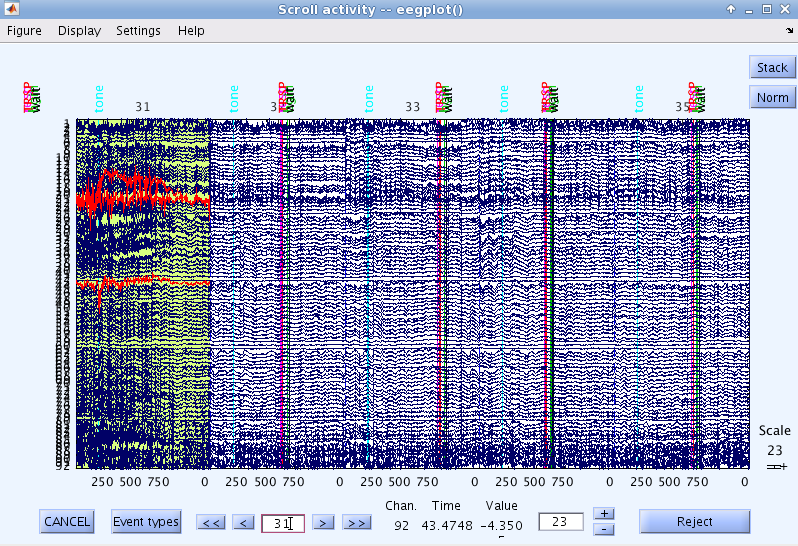

Demo#2 Trial rejection by trend(slope)

opts.reject = 1; opts.recon = 0;
opts.threshold = 0; opts.slope = 1;
[EEG_Demo2] = preprocess_manageBadTrials(EEG_Demo2,opts);

Selecting trials...
92 channel(s) selected
51/324 trial(s) marked for rejection
The following trials have been marked for rejection
8   13   18   22   47   51   55   58   60   64   69   77   80   84   85  103  105  106  108  119  120  124  127  133  167  171  173  176  181  183  187  201  205  206  219  225  229  235  244  251  260  285  288  291  300  301  307  310  312  314  322


<--------Summary------------->
The following epochs have been marked for rejection after manual inspection 
8   13   18   22   47   51   55   58   60   64   69   77   80   84   85  103  105  106  108  119  120  124  127  133  167  171  173  176  181  183  187  201  205  206  219  225  229  235  244  251  260  285  288  291  300  301  307  310  312  314  322
Removing 51 trial(s)...
Pop_select: removing 197 unreferenced events
eeg_checkset: found empty values for field 'value'
              filling with values of other events in the same epochs


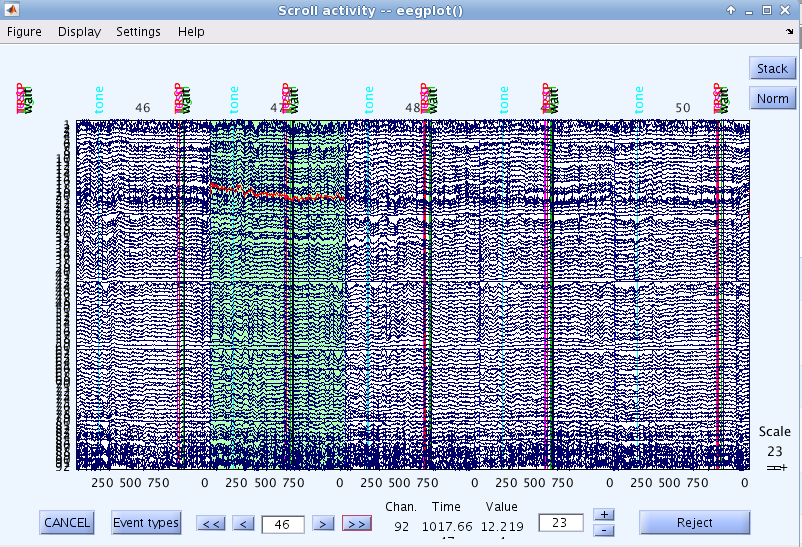

Demo#3 Trial reconstruction by amplitude

opts.reject = 0; opts.recon = 1;
opts.threshold = 1; opts.slope = 0;
[EEG_Demo3] = preprocess_manageBadTrials(EEG_Demo3,opts);

92 channel selected
4/324 trials marked for rejection
The following epochs have been marked for rejection after thresholds 
31  120  235  271



Interpolating bad channels in a trial by trial manner...
Removing 323 trial(s)...
Pop_select: removing 1207 unreferenced events

 Replacing electrodes 20,21,44 in trial 31
Using spherical interpolation
Removing 3 channel(s)...
Interpolating missing channels...
Removing 323 trial(s)...
Pop_select: removing 1203 unreferenced events

 Replacing electrodes 31 in trial 32
Using spherical interpolation
Removing 1 channel(s)...
Interpolating missing channels...
Removing 323 trial(s)...
Pop_select: removing 1203 unreferenced events

 Replacing electrodes 1 in trial 120
Using spherical interpolation
Removing 1 channel(s)...
Interpolating missing channels...
Removing 323 trial(s)...
Pop_select: removing 1203 unreferenced events

 Replacing electrodes 20 in trial 235
Using spherical interpolation
Removing 1 channel(s)...
Interpolating missing channels...
Removing 323 trial(s)...
Pop_select: removing 1203 unreferenced events

 Replacing electrodes 29 in trial 271
Using spherical interpolation
Rem